# Labrador Sea Cyclone Plotting Script

## Reading in all years of data to create nested directories

% Specify the folder where the files live
myFolder = 'C:\Users\terri\Documents\MATLAB\ERA5Lab'

myFolder = 'C:\Users\terri\Documents\MATLAB\ERA5Lab'

% Check to make sure the folder actually exists. Warn user if it doesn't
if ~isfolder(myFolder)
    errorMessage = sprintf('Error: The following folder does not exist:\n%s\nPlease specify a new folder.', myFolder);
    uiwait(warndlg(errorMessage));
    myFolder = uigetdir(); % Ask for a new one.
    if myFolder == 0
         % User clicked Cancel
         return;
    end
end

% Create struct containing tables for each year's data.
filePattern = fullfile(myFolder, '*.csv');
ERA5Lab = dir(filePattern);
n = length(ERA5Lab);

for ix = 1:n
    baseFileName = ERA5Lab(ix).name;
    fullFileName = fullfile(ERA5Lab(ix).folder, baseFileName);
    fprintf(1, 'Now reading %s\n', fullFileName);
    [ERA5Lab(ix).Data] = readtable(fullFileName);
end

baseFileName = '2002_ERA5_Lab_Candidates.csv'

Now reading C:\Users\terri\Documents\MATLAB\ERA5Lab\2002_ERA5_Lab_Candidates.csv


baseFileName = '2003_ERA5_Lab_Candidates.csv'

Now reading C:\Users\terri\Documents\MATLAB\ERA5Lab\2003_ERA5_Lab_Candidates.csv


baseFileName = '2004_ERA5_Lab_Candidates.csv'

Now reading C:\Users\terri\Documents\MATLAB\ERA5Lab\2004_ERA5_Lab_Candidates.csv


baseFileName = '2005_ERA5_Lab_Candidates.csv'

Now reading C:\Users\terri\Documents\MATLAB\ERA5Lab\2005_ERA5_Lab_Candidates.csv


baseFileName = '2006_ERA5_Lab_Candidates.csv'

Now reading C:\Users\terri\Documents\MATLAB\ERA5Lab\2006_ERA5_Lab_Candidates.csv


baseFileName = '2007_ERA5_Lab_Candidates.csv'

Now reading C:\Users\terri\Documents\MATLAB\ERA5Lab\2007_ERA5_Lab_Candidates.csv


baseFileName = '2008_ERA5_Lab_Candidates.csv'

Now reading C:\Users\terri\Documents\MATLAB\ERA5Lab\2008_ERA5_Lab_Candidates.csv


baseFileName = '2009_ERA5_Lab_Candidates.csv'

Now reading C:\Users\terri\Documents\MATLAB\ERA5Lab\2009_ERA5_Lab_Candidates.csv


baseFileName = '2010_ERA5_Lab_Candidates.csv'

Now reading C:\Users\terri\Documents\MATLAB\ERA5Lab\2010_ERA5_Lab_Candidates.csv


baseFileName = '2011_ERA5_Lab_Candidates.csv'

Now reading C:\Users\terri\Documents\MATLAB\ERA5Lab\2011_ERA5_Lab_Candidates.csv


baseFileName = '2012_ERA5_Lab_Candidates.csv'

Now reading C:\Users\terri\Documents\MATLAB\ERA5Lab\2012_ERA5_Lab_Candidates.csv


baseFileName = '2013_ERA5_Lab_Candidates.csv'

Now reading C:\Users\terri\Documents\MATLAB\ERA5Lab\2013_ERA5_Lab_Candidates.csv


baseFileName = '2014_ERA5_Lab_Candidates.csv'

Now reading C:\Users\terri\Documents\MATLAB\ERA5Lab\2014_ERA5_Lab_Candidates.csv


baseFileName = '2015_ERA5_Lab_Candidates.csv'

Now reading C:\Users\terri\Documents\MATLAB\ERA5Lab\2015_ERA5_Lab_Candidates.csv


baseFileName = '2016_ERA5_Lab_Candidates.csv'

Now reading C:\Users\terri\Documents\MATLAB\ERA5Lab\2016_ERA5_Lab_Candidates.csv


baseFileName = '2017_ERA5_Lab_Candidates.csv'

Now reading C:\Users\terri\Documents\MATLAB\ERA5Lab\2017_ERA5_Lab_Candidates.csv


baseFileName = '2018_ERA5_Lab_Candidates.csv'

Now reading C:\Users\terri\Documents\MATLAB\ERA5Lab\2018_ERA5_Lab_Candidates.csv


baseFileName = '2019_ERA5_Lab_Candidates.csv'

Now reading C:\Users\terri\Documents\MATLAB\ERA5Lab\2019_ERA5_Lab_Candidates.csv


## Import Data (single year)

opts = delimitedTextImportOptions("NumVariables", 10);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["track_id", "year", "month", "day", "hour", "i", "j", "lon", "lat", "msl"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
LabCandidates2019 = readtable("C:\Users\terri\Documents\MATLAB\ERA5Lab\2019_ERA5_Lab_Candidates.csv", opts);
clear opts

## Figure


% Defining variables for the columns in the cyclone data 
% LabCandidatesT = table2array(LabCandidates);
% trackIDT = LabCandidatesT(:, 1);
% monthT = LabCandidatesT(:, [3 8 9]);
% dayT = LabCandidatesT(:, 4);
% hourT = LabCandidatesT(:, 5);
% lon1 = LabCandidatesT(:, 8);
% lat1 = LabCandidatesT(:, 9);
% n =  max(trackIDT);

i = max(ERA5Lab(xx).Data.track_id);
sa = {'2002 Labrador Sea ERA5','2003 Labrador Sea ERA5','2004 Labrador Sea ERA5','2005 Labrador Sea ERA5','2006 Labrador Sea ERA5','2007 Labrador Sea ERA5','2008 Labrador Sea ERA5','2009 Labrador Sea ERA5','2010 Labrador Sea ERA5','2011 Labrador Sea ERA5','2012 Labrador Sea ERA5','2013 Labrador Sea ERA5','2014 Labrador Sea ERA5','2015 Labrador Sea ERA5','2016 Labrador Sea ERA5','2017 Labrador Sea ERA5','2018 Labrador Sea ERA5','2019 Labrador Sea ERA5'};

for xx = 1:18
    Jan = ERA5Lab(xx).Data(ERA5Lab(xx).Data.month == 1, :); % Defining tables for each month's data
    Feb = ERA5Lab(xx).Data(ERA5Lab(xx).Data.month == 2, :);
    Mar = ERA5Lab(xx).Data(ERA5Lab(xx).Data.month == 3, :);
    Apr = ERA5Lab(xx).Data(ERA5Lab(xx).Data.month == 4, :);
    May = ERA5Lab(xx).Data(ERA5Lab(xx).Data.month == 5, :);
    Jun = ERA5Lab(xx).Data(ERA5Lab(xx).Data.month == 6, :);
    Jul = ERA5Lab(xx).Data(ERA5Lab(xx).Data.month == 7, :);
    Aug = ERA5Lab(xx).Data(ERA5Lab(xx).Data.month == 8, :);
    Sep = ERA5Lab(xx).Data(ERA5Lab(xx).Data.month == 9, :);
    Oct = ERA5Lab(xx).Data(ERA5Lab(xx).Data.month == 10, :);
    Nov = ERA5Lab(xx).Data(ERA5Lab(xx).Data.month == 11, :);
    Dec = ERA5Lab(xx).Data(ERA5Lab(xx).Data.month == 12, :);
    for b = 0:i
        latJan = Jan.lat(Jan.track_id == b);
        lonJan = Jan.lon(Jan.track_id == b);
        geoplot(latJan,lonJan,'.-','Color',cc(1,:)); % colours specified so that DJF will be easy to visualize
        hold on
        latFeb = Feb.lat(Feb.track_id == b);
        lonFeb = Feb.lon(Feb.track_id == b);
        geoplot(latFeb,lonFeb,'.-','Color',dd(7,:));
        hold on 
        latMar = Mar.lat(Mar.track_id == b);
        lonMar = Mar.lon(Mar.track_id == b);
        geoplot(latMar,lonMar,'.-','Color',cc(4,:));
        hold on 
        latApr = Apr.lat(Apr.track_id == b);
        lonApr = Apr.lon(Apr.track_id == b);
        geoplot(latApr,lonApr,'.-','Color',cc(3,:));
        hold on 
        latMay = May.lat(May.track_id == b);
        lonMay = May.lon(May.track_id == b);
        geoplot(latMay,lonMay,'.-','Color',cc(6,:));
        hold on 
        latJun = Jun.lat(Jun.track_id == b);
        lonJun = Jun.lon(Jun.track_id == b);
        geoplot(latJun,lonJun,'.-','Color',cc(8,:));
        hold on 
        latJul = Jul.lat(Jul.track_id == b);
        lonJul = Jul.lon(Jul.track_id == b);
        geoplot(latJul,lonJul,'.-','Color',cc(12,:));
        hold on 
        latAug = Aug.lat(Aug.track_id == b);
        lonAug = Aug.lon(Aug.track_id == b);
        geoplot(latAug,lonAug,'.-','Color',cc(10,:));
        hold on 
        latSep = Sep.lat(Sep.track_id == b);
        lonSep = Sep.lon(Sep.track_id == b);
        geoplot(latSep,lonSep,'.-','Color',cc(7,:));
        hold on 
        latOct = Oct.lat(Oct.track_id == b);
        lonOct = Oct.lon(Oct.track_id == b);
        geoplot(latOct,lonOct,'.-','Color',cc(11,:));
        hold on 
        latNov = Nov.lat(Nov.track_id == b);
        lonNov = Nov.lon(Nov.track_id == b);
        geoplot(latNov,lonNov,'.-','Color',cc(9,:));
        hold on 
        latDec = Dec.lat(Dec.track_id == b);
        lonDec = Dec.lon(Dec.track_id == b);
        geoplot(latDec,lonDec,'.-','Color',cc(5,:));
        hold on 
    end
    geobasemap('topographic')
    title(sa(xx))
    exportgraphics(gca, ['Tracks' num2str(xx+2001) 'LabERA5.png'],"Resolution",300);
    clf
end

## Exporting the figure

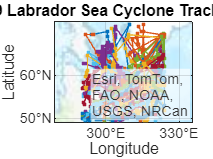

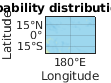

SWITCH expression must be a scalar or a character vector.

exportgraphics(gca,"LabERA52019.png","Resolution",300)

## Defining tables for each month's data

% will need to add this to the loop from 1:18
Jan = ERA5Lab(xx).Data(ERA5Lab(xx).Data.month == 1, :);
Feb = ERA5Lab(xx).Data(ERA5Lab(xx).Data.month == 2, :);
Mar = ERA5Lab(xx).Data(ERA5Lab(xx).Data.month == 3, :);
Apr = ERA5Lab(xx).Data(ERA5Lab(xx).Data.month == 4, :);
May = ERA5Lab(xx).Data(ERA5Lab(xx).Data.month == 5, :);
Jun = ERA5Lab(xx).Data(ERA5Lab(xx).Data.month == 6, :);
Jul = ERA5Lab(xx).Data(ERA5Lab(xx).Data.month == 7, :);
Aug = ERA5Lab(xx).Data(ERA5Lab(xx).Data.month == 8, :);
Sep = ERA5Lab(xx).Data(ERA5Lab(xx).Data.month == 9, :);
Oct = ERA5Lab(xx).Data(ERA5Lab(xx).Data.month == 10, :);
Nov = ERA5Lab(xx).Data(ERA5Lab(xx).Data.month == 11, :);
Dec = ERA5Lab(xx).Data(ERA5Lab(xx).Data.month == 12, :);

## Making monthly plots & colour coding

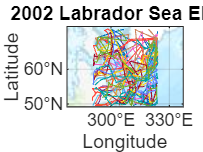

cc = orderedcolors("gem12"); % gem12 is relatively colorblind-friendly I think
dd = orderedcolors("glow12");

i = max(ERA5Lab(1).Data.track_id);

for b = 0:i
    latJan = Jan.lat(Jan.track_id == b);
    lonJan = Jan.lon(Jan.track_id == b);
    geoplot(latJan,lonJan,'Color',cc(1,:)); % colours specified so that DJF will be easy to visualize
    hold on
    latFeb = Feb.lat(Feb.track_id == b);
    lonFeb = Feb.lon(Feb.track_id == b);
    geoplot(latFeb,lonFeb,'Color',dd(7,:));
    hold on 
    latMar = Mar.lat(Mar.track_id == b);
    lonMar = Mar.lon(Mar.track_id == b);
    geoplot(latMar,lonMar,'Color',cc(4,:));
    hold on 
    latApr = Apr.lat(Apr.track_id == b);
    lonApr = Apr.lon(Apr.track_id == b);
    geoplot(latApr,lonApr,'Color',cc(3,:));
    hold on 
    latMay = May.lat(May.track_id == b);
    lonMay = May.lon(May.track_id == b);
    geoplot(latMay,lonMay,'Color',cc(6,:));
    hold on 
    latJun = Jun.lat(Jun.track_id == b);
    lonJun = Jun.lon(Jun.track_id == b);
    geoplot(latJun,lonJun,'Color',cc(8,:));
    hold on 
    latJul = Jul.lat(Jul.track_id == b);
    lonJul = Jul.lon(Jul.track_id == b);
    geoplot(latJul,lonJul,'Color',cc(12,:));
    hold on 
    latAug = Aug.lat(Aug.track_id == b);
    lonAug = Aug.lon(Aug.track_id == b);
    geoplot(latAug,lonAug,'Color',cc(10,:));
    hold on 
    latSep = Sep.lat(Sep.track_id == b);
    lonSep = Sep.lon(Sep.track_id == b);
    geoplot(latSep,lonSep,'Color',cc(7,:));
    hold on 
    latOct = Oct.lat(Oct.track_id == b);
    lonOct = Oct.lon(Oct.track_id == b);
    geoplot(latOct,lonOct,'Color',cc(11,:));
    hold on 
    latNov = Nov.lat(Nov.track_id == b);
    lonNov = Nov.lon(Nov.track_id == b);
    geoplot(latNov,lonNov,'Color',cc(9,:));
    hold on 
    latDec = Dec.lat(Dec.track_id == b);
    lonDec = Dec.lon(Dec.track_id == b);
    geoplot(latDec,lonDec,'Color',cc(5,:));
    hold on 
end
geobasemap('topographic')
title('2002 Labrador Sea ERA5')

## Plotting a single track

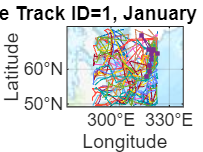

latx = ERA5Lab(1).Data.lat(ERA5Lab(1).Data.track_id == 0);
lonx = ERA5Lab(1).Data.lon(ERA5Lab(1).Data.track_id == 0);
geoplot(latx,lonx,'.-')
geobasemap('topographic')
title('Cyclone Track ID=0, January 2002 (ERA5)')

## Geodensityplot

latAll = LabCandidates2019.lat;
lonAll = LabCandidates2019.lon;
geodensityplot(latAll,lonAll)
geobasemap("bluegreen")
title('Cumulative probability distribution of cyclones, 2015')

## Monthly tracks- attempt to use switch

% for b = 0:i
% for LabCandidatesT
%     switch monthT 
%         case LabCandidates.month == 1
%             geoplot(lat2,lon2,'.-')
%             geolimits([45 70],[290 324])
%             hold on
%             geobasemap('colorterrain')
%             title(['month',num2str(month),'tracks'])
%         case 2
%             geoplot(lat2,lon2,'.-')
%             geolimits([45 70],[290 324])
%             hold on
%             geobasemap('colorterrain')
%             title(['month',num2str(month),'tracks'])
%         case 3
%             geoplot(lat2,lon2,'.-')
%             geolimits([45 70],[290 324])
%             hold on
%             geobasemap('colorterrain')
%             title(['month',num2str(month),'tracks'])
%         case 4
%             geoplot(lat2,lon2,'.-')
%             geolimits([45 70],[290 324])
%             hold on
%             geobasemap('colorterrain')
%             title(['month',num2str(month),'tracks'])
%         case 5
%             geoplot(lat2,lon2,'.-')
%             geolimits([45 70],[290 324])
%             hold on
%             geobasemap('colorterrain')
%             title(['month',num2str(month),'tracks'])
%         case 6
%             geoplot(lat2,lon2,'.-')
%             geolimits([45 70],[290 324])
%             hold on
%             geobasemap('colorterrain')
%             title(['month',num2str(month),'tracks'])
%         case 7
%             geoplot(lat2,lon2,'.-')
%             geolimits([45 70],[290 324])
%             hold on
%             geobasemap('colorterrain')
%             title(['month',num2str(month),'tracks'])
%         case 8
%             geoplot(lat2,lon2,'.-')
%             geolimits([45 70],[290 324])
%             hold on
%             geobasemap('colorterrain')
%             title(['month',num2str(month),'tracks'])
%         case 9
%             geoplot(lat2,lon2,'.-')
%             geolimits([45 70],[290 324])
%             hold on
%             geobasemap('colorterrain')
%             title(['month',num2str(month),'tracks'])
%         case 10
%             geoplot(lat2,lon2,'.-')
%             geolimits([45 70],[290 324])
%             hold on
%             geobasemap('colorterrain')
%             title(['month',num2str(month),'tracks'])
%         case 11
%             geoplot(lat2,lon2,'.-')
%             geolimits([45 70],[290 324])
%             hold on
%             geobasemap('colorterrain')
%             title(['month',num2str(month),'tracks'])
%         case 12
%             geoplot(lat2,lon2,'.-')
%             geolimits([45 70],[290 324])
%             hold on
%             geobasemap('colorterrain')
%             title(['month',num2str(month),'tracks'])
%     end
% end